# Optical Abosrption MATLAB code

load('/Users/harold/Documents/Academia/Nottingham Uni/Year 2/Intermediate Experimental Physics (PHYS2005)/Experiments/Lab Reports/Optical Absorption of Semiconductors/MATLAB for optical/Alda MATLAB help/I02.mat')
load('/Users/harold/Documents/Academia/Nottingham Uni/Year 2/Intermediate Experimental Physics (PHYS2005)/Experiments/Lab Reports/Optical Absorption of Semiconductors/MATLAB for optical/Alda MATLAB help/I3.mat')
load('/Users/harold/Documents/Academia/Nottingham Uni/Year 2/Intermediate Experimental Physics (PHYS2005)/Experiments/Lab Reports/Optical Absorption of Semiconductors/MATLAB for optical/Alda MATLAB help/lambda.mat')
load('/Users/harold/Documents/Academia/Nottingham Uni/Year 2/Intermediate Experimental Physics (PHYS2005)/Experiments/Lab Reports/Optical Absorption of Semiconductors/MATLAB for optical/Alda MATLAB help/low_energies_alpha.mat')
load('/Users/harold/Documents/Academia/Nottingham Uni/Year 2/Intermediate Experimental Physics (PHYS2005)/Experiments/Lab Reports/Optical Absorption of Semiconductors/MATLAB for optical/Alda MATLAB help/high_energies_alpha.mat')

% loads all the data for this experiment

RefractiveIndexInfo = csvimport('/Users/harold/Documents/Academia/Nottingham Uni/Year 4/Research Project/Report/Coding/RefractiveIndexINFO.csv');

Error using csvimport (line 167)
Failed to open '/Users/harold/Documents/Academia/Nottingham Uni/Year 4/Research Project/Report/Coding/RefractiveIndexINFO.csv' for reading.
Error Message: No such file or directory

RefractiveIndexInfo(1,:) = [];
%RefractiveIndexInfo_GaAs = cellfun(@str2double, RefractiveIndexInfo_GaAs);
RefractiveIndexInfo_GaAs = zeros(46,3);

for c=1:3
    for r=1:46
        RefractiveIndexInfo_GaAs(r,c) = RefractiveIndexInfo{r,c};
    end
end

L = RefractiveIndexInfo_GaAs(:,1).*1000;
N = RefractiveIndexInfo_GaAs(:,2);
K = RefractiveIndexInfo_GaAs(:,3);

plot(L,N)
hold on
plot(L,K)
hold off

%nearestRefraction(L, Lambda, N);

T_0 = abs(I3./I02);
% whole data set of T recorded
T = T_0(349:410);
Lambda=LambdaStore(349:410);
% confining T and lambda to regiojn of interest
% also making sure they are the same size

figure
plot(Lambda,T,'*')
xlabel('Wavelength/nm')
ylabel('Transmission Coefficient')
title({'Transmission Coefficient vs Optical Wavelength taken on',
    'Gallium Phosphide Sample'})
hold off

% btw i dont think they like titles in matlab graphs i think they prefder a
% caption but just check in the formal report guide

n = zeros(size(Lambda));
R = zeros(size(Lambda));

for i=1:size(Lambda,2)
    n = nearestRefraction(L, Lambda(i), N);
    k = nearestRefraction(L, Lambda(i), K);
    %n=3.1870;
    % value of n quoted from [source]
    % R(i) = ((n-1))/((n+1));
    R(i) = ((n-1)+k.^2)/((n+1)+k.^2);

    % approximated value of R calculated
    % Are you not calculating R manually, or just using the estimate?

end


x = 0.408*10^-3;
% thickness of sample
xerr = 0.001*10^-3;
% error on thickness
h = 6.63*10^-34;
% planks constant
c = 2.99*10^8;
% speed of light
energy_ev = h*c./(Lambda.*10^-9*1.6*10^-19);
% calculates the energy in eV for the respective wavelengths


% for large wavelengths then extrapolate with curve fitting tool
% rootalpha  = (-x^(-1).*log([((1-R).^4+4.*T1.^2.*R.^2).^1/2-(1-R).^2]/2.*T1.*R.^2)).^1/2;
% for small wavelengths find curve
% not really to sure whats going on with the section above as you're
% subtracting alpha from itself so alphae is just 0 in this case

% Also check this equation I've changed it a lot one thing to remeber
% divition and multiplication involving arrays has to be used by using '.'
% if you forget to put the full stop then it doesn't divide individually

% Anyway i think this equation is right, its the same as mine now but just
% check anyway just in case
rootalpha = -x^(-1).*log((((1 - R).^4 + 4.*(T.^2).*(R.^2)).^0.5 - (1 - R).^2)./(2.*T.*(R.^2)));

figure
plot(energy_ev,rootalpha,'*')
pbs = predint(Alda_low_energy_alpha,energy_ev,0.68);
hold on
plot(Alda_low_energy_alpha)
hold on
plot(energy_ev,pbs,'m--')
xlabel('Energy / eV')
ylabel('Square root of alpha')
legend('off')
hold off

% plots rootalpha vs energy with line of best fit in low energy region
% you can fiddle round with the limit to get a good looking graph

A = 3.728/1.722 % this is the value of Eg - Ep

alphaa = (energy_ev - A).^2;
% technically alpha a over c
% calculates value of alpha a needed for alpha e

alphae = (rootalpha - alphaa).^(0.5);
% calculates value of alpha e^(0.5)

figure
plot(energy_ev,alphae,'*')
pbs = predint(Alda_high_energies_alpha,energy_ev,0.68);
hold on
plot(Alda_high_energies_alpha)
hold on
plot(energy_ev,pbs,'m--')
xlabel('Energy / eV')
ylabel('Square root of alpha_e')
legend('off')
hold off
xlabel('Optical Energy (eV)')
ylabel('Absorption Coefficient of e to the half')
% plots alpha_e vs enegy to find Eg + Ep

B = 2042/931.8 % this is the value for Eg + Eg

bandgap = (A + B)/2 % band gap energy
phonon = (B - A)/2 % phonon energy

% you dont have errors for anything atm on the graph, you could do error bars
% if you want

% you dont have many points so thats maybe why the band gap is slightly off
% but all in all its very close

% on things to be wary of is that you cant propagate error to get the error
% on the x interecept using the error propagation equation, if you do
% theyll mark you down.

%rootalphae=rootalpha-rootalphaa;
% % for values with equal energy subtract curves from fittedmodels from each
% % other

%hold on
%plot(E,rootalphaa);
%plot(E,rootalpha);
% % x1 intercept= Eg-Ep CURVE FITTING
%hold off
% %% 5)
% plot(E,rootalphae);
% % x2 intercept= Eg+Ep CURVE FITTING
% %% 6)
% Eg=(x1+x2)./2;
% Ep=(x2-x1)./2;


# Test

g = []


g =

     []



g(1) = T(1)./(Lambda(1));
for i=2:size(Lambda,2)-1
    g(i) = (T(i+1) - T(i))./(Lambda(i+1) - Lambda(i));
end
data = smoothdata(g);
StraightLine = [];
for i = 1:size(data,2)-1
    section = data(i:i+1);
    p12 = section(1);
    p23 = section(2);
    per = p23*0.05;

    if (p23-per <= p12) && (p12 <= p23+per)
       StraightLine(i) = section(1);
    end
end

nonzero = find(StraightLine ~= 0)

nonzero =     28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    54    55    59


StraightLine = T(nonzero)

StraightLine =     0.0929    0.1061    0.1212    0.1395    0.1588    0.1757    0.1938    0.2100    0.2325    0.2531    0.2699    0.2861    0.3026    0.3223    0.3387    0.3515    0.4765    0.4854    0.4988


LambdaStraightLine = Lambda(nonzero)

LambdaStraightLine =   547.9250  548.5844  549.2438  549.9031  550.5625  551.2219  551.8813  552.5406  553.2000  553.8594  554.5188  555.1781  555.8375  556.4969  557.1563  557.8156  565.0688  565.7281  568.3656


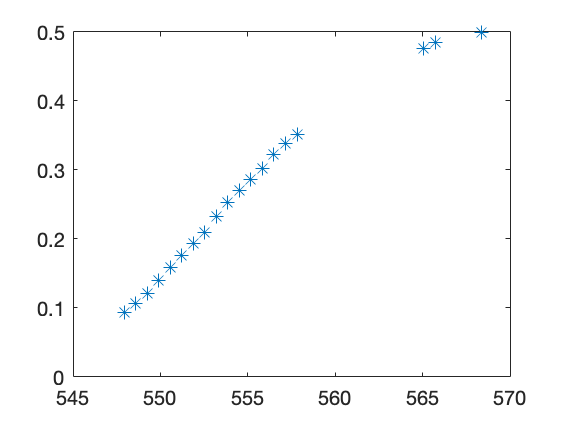

plot(LambdaStraightLine, StraightLine, '*')
hold off


[length, index] = LongestConsecutive2(nonzero)

longestLength = 0


longestLengthIndex =

     []



currLength = 1

ans =      1    19


length = 16

index = 16

nonzero_corrected = nonzero(index-length+1:index)

nonzero_corrected =     28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43


StraightLine = T(nonzero_corrected)

StraightLine =     0.0929    0.1061    0.1212    0.1395    0.1588    0.1757    0.1938    0.2100    0.2325    0.2531    0.2699    0.2861    0.3026    0.3223    0.3387    0.3515


LambdaStraightLine = Lambda(nonzero_corrected)

LambdaStraightLine =   547.9250  548.5844  549.2438  549.9031  550.5625  551.2219  551.8813  552.5406  553.2000  553.8594  554.5188  555.1781  555.8375  556.4969  557.1563  557.8156


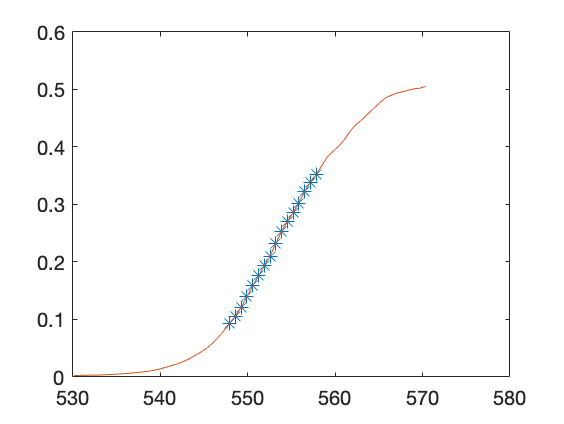

plot(LambdaStraightLine, StraightLine, '*')
hold on
plot(Lambda, T)
hold off

# Functions

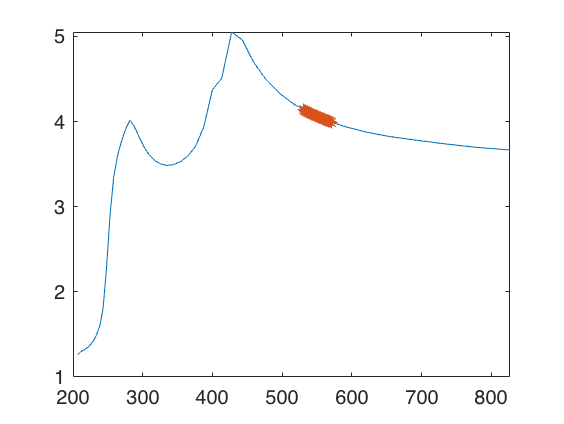

n = zeros(size(Lambda));
R = zeros(size(Lambda));

for i=1:size(Lambda,2)
    n(i) = nearestRefraction(L, Lambda(i), N);
end

plot(L,N)
hold on
plot(Lambda,n,'*')

## Test 2

array = [1,2,3,4,5,6,9,10,11,12,13,14,15,16,17,18,20];
%[length, index] = LongestConsecutive(array);
[length, index] = LongestConsecutive2(array)

longestLength = 0


longestLengthIndex =

     []



currLength = 1

ans =      1    17


length = 10

index = 16

function RefractionTrueValue = nearestRefraction(LambdaStore, Lambda, RefractionIndex)

lambda_d = Lambda-LambdaStore;
lowest=max(find(lambda_d>0));
highest=lowest+1;

n_d = RefractionIndex(highest)- RefractionIndex(lowest);

Lambda_Percentage = lambda_d(lowest)./(LambdaStore(highest)-LambdaStore(lowest));

if n_d > 0
    RefractionTrueValue = RefractionIndex(lowest) - (n_d).* Lambda_Percentage;
elseif n_d < 0
    RefractionTrueValue = RefractionIndex(lowest) + (n_d).* Lambda_Percentage;
else 
    disp('Error Alert')
end
end

function StraightLine = DetectStraightLine(data)
data = smoothdata(data);
StraightLine = [];
for i = 1:size(data,2)
    section = data(i:i+1)
    p12 = section(i)
    p23 = section(i+1)
    per = p23*0.05

    if (p23-per <= p12) && (p12 <= p23+per)
       StraightLine(i) = section(i)
    end
end
end

function [LongestConsecutive, longestLengthIndex] = LongestConsecutive(X)

longestLength = 0

currLength = 1
size(X)
for i = 1:size(X,2)
    if i==1
        if X(i) == X(i + 1) - 1
                currLength = currLength + 1                
                longestLength = max(longestLength, currLength)   
        else
                currLength = 1
        end

    elseif i==size(X,2)
        if X(i) == X(i - 1) + 1
            currLength = currLength + 1
            longestLength = max(longestLength, currLength)
        else
            currLength = 1
        end

    elseif X(i) == X(i - 1) + 1
        if X(i) == X(i + 1) - 1
            currLength = currLength + 1
            longestLength = max(longestLength, currLength)
        else
            currLength = 1
        end
    end
    i
    if longestLength > currLength
        longestLengthIndex = i
    end

end
LongestConsecutive = max(longestLength, currLength)
end

function [LongestConsecutive, longestLengthIndex] = LongestConsecutive2(X)

longestLength = 0
longestLengthIndex = []

currLength = 1
size(X)
for i = 1:size(X,2)-1
    if X(i+1) == X(i) + 1
        currLength = currLength + 1;
        longestLength = max(longestLength, currLength);
    else
        currLength = 1;
        
    end
LongestConsecutive = max(longestLength, currLength);
if currLength == longestLength
    longestLengthIndex = i+1;
end

end
end

